# **Contact Point Analysis on Instrumented Treadmill**

*Comparison between motion capture estimation and force plate measurement*

### **Introduction**

This script aims to compare two methods for locating the contact point during a push on an instrumented treadmill: 

- The estimated point using trajectories from three markers attached to a calibration wand (captured via Vicon). 

- The center of pressure (COP) calculated from force plate measurements.

**The steps include:**

1. Retrieving marker trajectories using Vicon Nexus. 

2. Loading analog force data from a '.c3d' file. 

3. Estimating the contact point from marker positions. 

4. Computing the COP from force and moment data. 

5. Aligning both reference frames and comparing the results.

## **Marker Trajectory Acquisition**

We use the 'ViconNexus()' API to extract the trajectories of the markers attached to the calibration wand.

vicon = ViconNexus();
Markers = vicon.GetMarkerNames('treadmillCalibrationWand');
n = length(Markers);

trajX = cell(1,n);
trajY = cell(1,n);
trajZ = cell(1,n);
for i = 1:n
    [trajX{i}, trajY{i}, trajZ{i}, ~] = vicon.GetTrajectory('treadmillCalibrationWand', Markers{i});
end

N_marker = length(trajX{1}); %frames number
contact_z = 0;
P_contact = NaN(N_marker,3); %estimated contact point

## **Force Data Loading**

Analog force data is read from a '.c3d' file using the 'ezc3dRead' function. 

We extract the vertical force (Fz) and the necessary moments (Mx, My) for COP calculation.

acq = ezc3dRead('C:/Vicon/Maintenance/TreadMill/Cal3.c3d');
analog_data = acq.data.analogs;
labels = acq.parameters.ANALOG.LABELS.DATA;

fz_s = find(strcmp(labels, 'Force.Fz1'));
mx_s = find(strcmp(labels, 'Moment.Mx1'));
my_s = find(strcmp(labels, 'Moment.My1'));

Fz = analog_data(:, fz_s);
Mx = analog_data(:, mx_s);
My = analog_data(:, my_s);

## **Resampling and Filtering**

Since marker data and analog data have different sampling rates, we adjust the signal lengths accordingly. 

We also filter out frames with low vertical force (considered as invalid contact).

%synchonize force to marker sampling frequency
N_analog = size(analog_data, 1);
ratio = round(N_analog / N_marker);

Fz = Fz(1:ratio:end);
Mx = Mx(1:ratio:end);
My = My(1:ratio:end);

%crop to shortest length
min_N = min(length(Fz), N_marker);
Fz = Fz(1:min_N);
Mx = Mx(1:min_N);
My = My(1:min_N);
P_contact = P_contact(1:min_N, :);

% keeping only frames wherer force is above 50N
valide = abs(Fz) > 50;

## **Contact Point Estimation**

Using the positions of markers M1, M2, and M3, we estimate the center of the wand.

Assuming the wand is vertically aligned, we compute the contact point by extending it downward.

wand_length = 1250;

for t = 1:min_N
    if ~valide(t)
        continue;
    end
    
    M1 = [trajX{1}(t), trajY{1}(t), trajZ{1}(t)];
    M2 = [trajX{2}(t), trajY{2}(t), trajZ{2}(t)];
    M3 = [trajX{3}(t), trajY{3}(t), trajZ{3}(t)];

    center = (M3 + M1)/2;
    %pojection along z-axis
    direction = [0, 0, -1]; 
    P_contact(t,:) = center + wand_length * direction;
end

## **Center of Pressure (COP) Computation**

The COP is computed from the force and moment values using basic biomechanics formulas.

Invalid frames are ignored in the analysis

COP_x = My ./ Fz;
COP_y = -Mx ./ Fz;  %negative sign often necessary

%Remove the invalid frames
COP_x(~valide) = NaN;
COP_y(~valide) = NaN;

valid_points = ~isnan(COP_x) & ~isnan(P_contact(:,1));

% Application of the optimal offset
P1=[COP_x(valid_points), COP_y(valid_points)];
P2=P_contact(valid_points, 1:2);

[d, Z, transform] = procrustes(P1, P2); %Alignes P2 to P1 using rotation+translation


## **Alignment and Comparison**

To align the COP and the estimated contact point, we calculate the mean position of both and determine the optimal translation. 

We then apply this correction and plot the results.

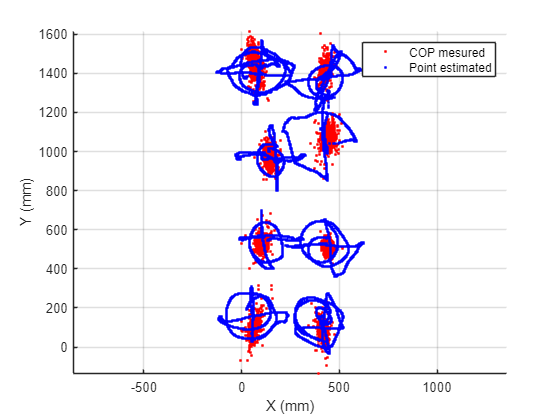

figure;
hold on;

plot(P1(:,1),P1(:,2),'r.','DisplayName','COP mesured');
plot(Z(:,1),Z(:,2),'b.','DisplayName','Point estimated');
xlabel('X (mm)');
ylabel('Y (mm)'); 
legend;
grid on;
axis equal;

%%error
for i = 1:size(Z,1)
    dists=vecnorm(P1 - Z(i,:),2,2); %Distance to all COPs
    min_dist(i)=min(dists); %keep the closest one
end
fprintf('Number of valid frames : %d\n', i);

Number of valid frames : 13695


fprintf('Mean error: %.2f mm\n',mean(min_dist));

Mean error: 42.42 mm


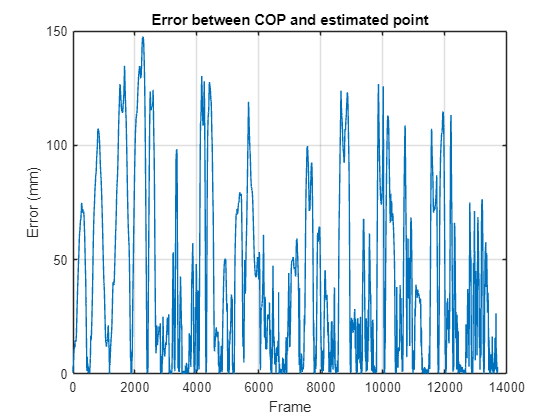

figure(2);
plot(min_dist);
xlabel('Frame');
ylabel('Error (mm)');
title('Error between COP and estimated point');
grid on;

## **Conclusion**

We evaluate the accuracy of the marker-based contact point estimation by comparing it to the COP. 

The average and maximum errors are reported to assess calibration quality.